# Solución de raíces con el método de la secante

#### Ejemplo 1 


$$x-\cos\left(x\right)=0$$


Definición de la función y su gráfica

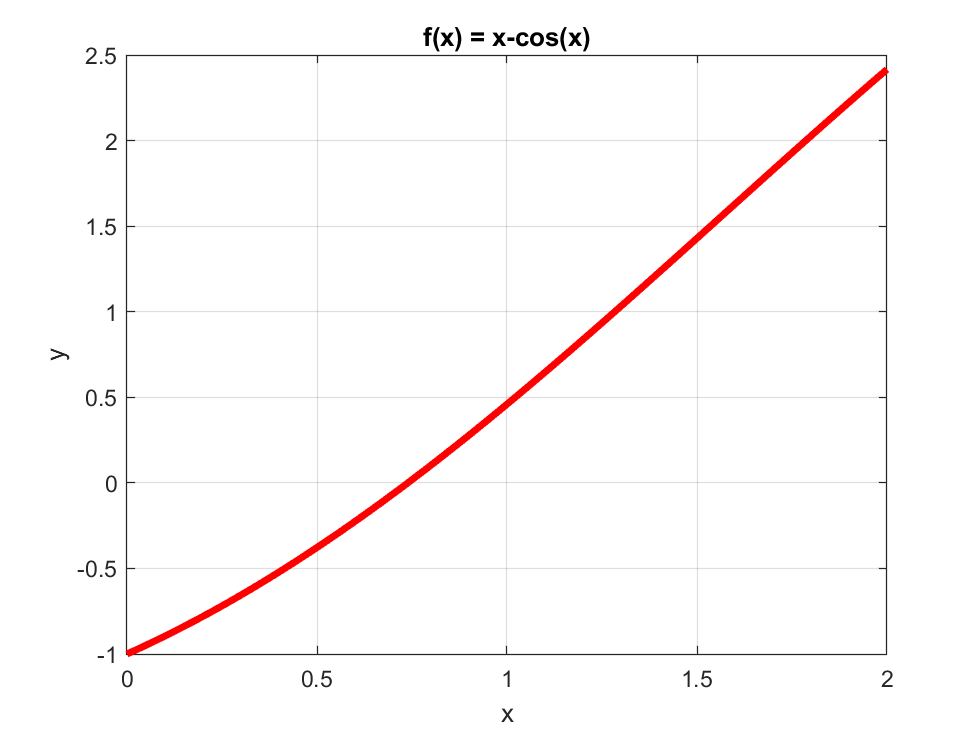

f = @(x) x-cos(x);

x = linspace(0, 2, 100);
plot(x, f(x), 'r', 'linewidth', 3)
grid on
xlabel('x')
ylabel('y')
title('f(x) = x-cos(x)')

Solución de la ecuación

xa = 0;
xb = 2;
errmax = 0.1;
[xr, fr, err] = secant(f, xa, xb, errmax);

x1: 0  f1: 0  x2: 2  f2: 2.4161  x3: 0.58545  f3: -0.24801  error: 241.6147
x1: 2  f1: 2  x2: 0.58545  f2: -0.24801  x3: 0.71713  f3: -0.036557  error: 18.3619
x1: 0.58545  f1: 0.58545  x2: 0.71713  f2: -0.036557  x3: 0.7399  f3: 0.0013653  error: 3.0769
x1: 0.71713  f1: 0.71713  x2: 0.7399  f2: 0.0013653  x3: 0.73908  f3: -6.6897e-06  error: 0.1109
x1: 0.7399  f1: 0.7399  x2: 0.73908  f2: -6.6897e-06  x3: 0.73909  f3: -1.2043e-09  error: 0.00054073


disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%") 

x = 0.73909  f(x) = -1.2043e-09  Error:0.00054073%


#### Ejemplo 2


$$xe^x=1$$
 

Definición de la función y su gráfica

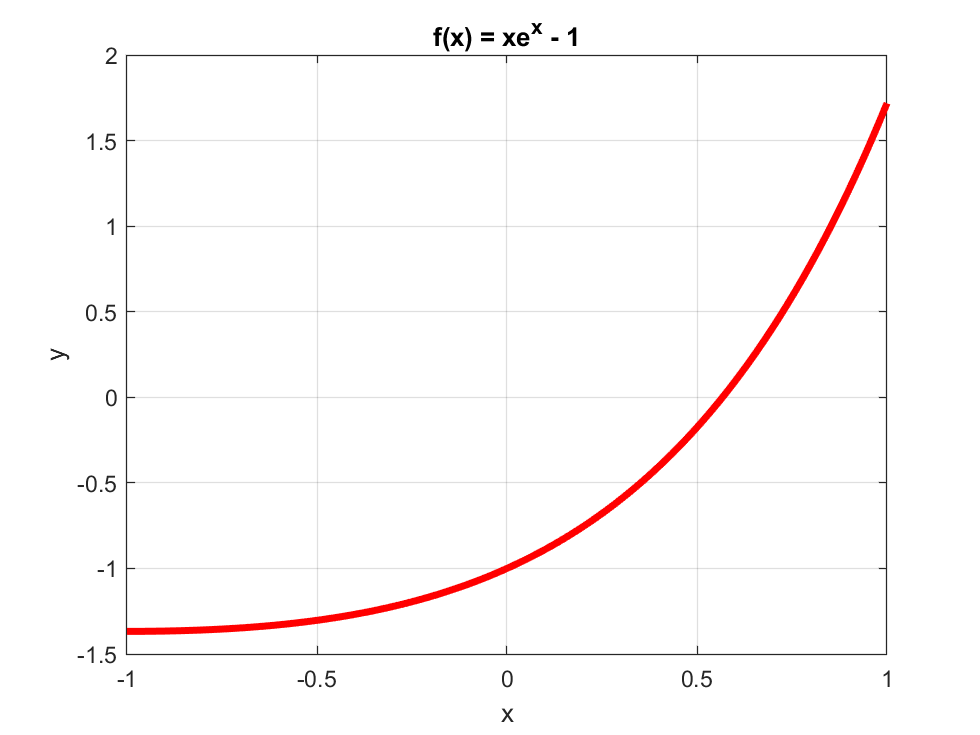

f = @(x) x.*exp(x) - 1;

x = linspace(-1, 1, 100);
plot(x, f(x), 'r', 'linewidth', 3)
grid on
xlabel('x')
ylabel('y')
title('f(x) = xe^x - 1')

Solución de la ecuación

xa = -1;
xb = 1;
errmax = 0.1;
[xr, fr, err] = secant(f, xa, xb, errmax);

x1: -1  f1: -1  x2: 1  f2: 1.7183  x3: -0.11354  f3: -1.1014  error: 980.7478
x1: 1  f1: 1  x2: -0.11354  f2: -1.1014  x3: 0.32141  f3: -0.55675  error: 135.3255
x1: -0.11354  f1: -0.11354  x2: 0.32141  f2: -0.55675  x3: 0.76606  f3: 0.64802  error: 58.044
x1: 0.32141  f1: 0.32141  x2: 0.76606  f2: 0.64802  x3: 0.52689  f3: -0.10762  error: 45.3925
x1: 0.76606  f1: 0.76606  x2: 0.52689  f2: -0.10762  x3: 0.56096  f3: -0.017008  error: 6.0722
x1: 0.52689  f1: 0.52689  x2: 0.56096  f2: -0.017008  x3: 0.56735  f3: 0.00057305  error: 1.1269
x1: 0.56096  f1: 0.56096  x2: 0.56735  f2: 0.00057305  x3: 0.56714  f3: -2.9093e-06  error: 0.036746


disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = 0.56714  f(x) = -2.9093e-06  Error:0.036746%


#### Ejemplo 3


$$x\:\log_{10}\left(x\right)=1.2$$


Definición de la función y su gráfica

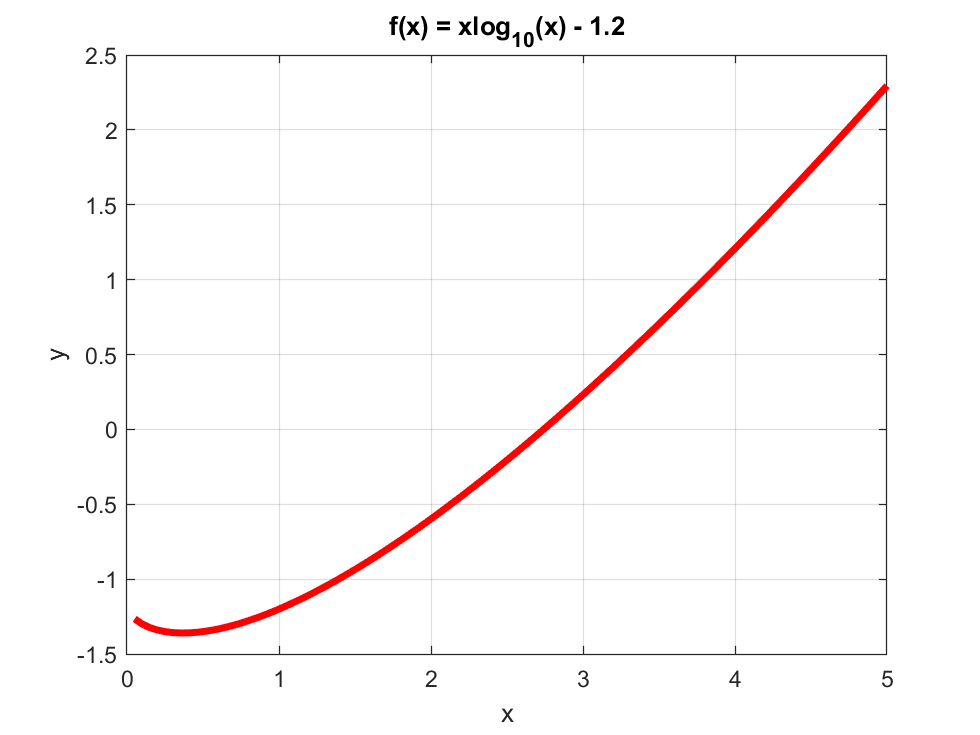

f = @(x) x.*log10(x) - 1.2;

x = linspace(0, 5, 100);
plot(x, f(x), 'r', 'linewidth', 3)
grid on
xlabel('x')
ylabel('y')
title('f(x) = xlog_1_0(x) - 1.2')

Solución de la ecuación

xa = 1;
xb = 5;
errmax = 0.1;
[xr, fr, err] = secant(f, xa, xb, errmax);

x1: 1  f1: 1  x2: 5  f2: 2.2949  x3: 2.3734  f3: -0.30905  error: 110.6638
x1: 5  f1: 5  x2: 2.3734  f2: -0.30905  x3: 2.6852  f3: -0.048119  error: 11.6097
x1: 2.3734  f1: 2.3734  x2: 2.6852  f2: -0.048119  x3: 2.7427  f3: 0.0017742  error: 2.0961
x1: 2.6852  f1: 2.6852  x2: 2.7427  f2: 0.0017742  x3: 2.7406  f3: -9.0396e-06  error: 0.074593


disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = 2.7406  f(x) = -9.0396e-06  Error:0.074593%


#### Ejemplo 4


$$e^{0.3x}-x^2=-4$$


Definición de la función y su gráfica

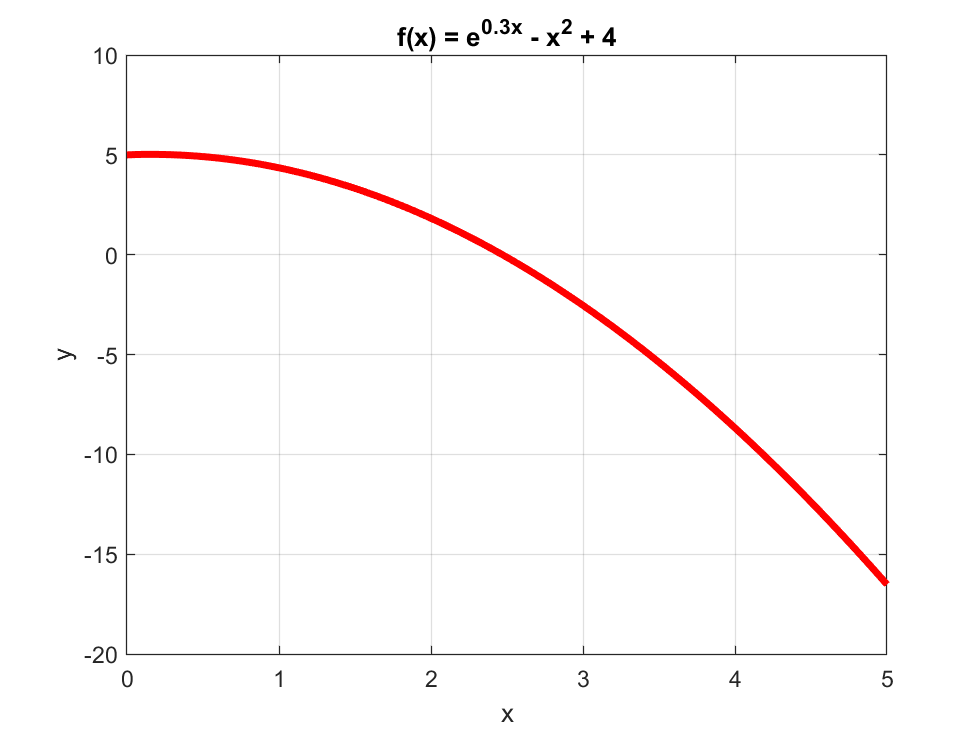

f = @(x) exp(0.3*x) - x.^2 + 4;

x = linspace(0, 5, 100);
plot(x, f(x), 'r', 'linewidth', 3)
grid on
xlabel('x')
ylabel('y')
title('f(x) = e^0^.^3^x - x^2 + 4')

Solución de la ecuación

xa = 1;
xb = 5;
errmax = 0.1;
[xr, fr, err] = secant(f, xa, xb, errmax);

x1: 1  f1: 1  x2: 5  f2: -16.5183  x3: 1.8338  f3: 2.3707  error: 172.661
x1: 5  f1: 5  x2: 1.8338  f2: 2.3707  x3: 2.2312  f3: 0.97486  error: 17.8108
x1: 1.8338  f1: 1.8338  x2: 2.2312  f2: 0.97486  x3: 2.5087  f3: -0.17103  error: 11.0627
x1: 2.2312  f1: 2.2312  x2: 2.5087  f2: -0.17103  x3: 2.4673  f3: 0.0088753  error: 1.6789
x1: 2.5087  f1: 2.5087  x2: 2.4673  f2: 0.0088753  x3: 2.4693  f3: 7.2848e-05  error: 0.082756


disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = 2.4693  f(x) = 7.2848e-05  Error:0.082756%


#### Ejemplo 5


$$2\cos\left(x\right)-\frac{\sqrt{x}}{2}=1$$
 

Definición de la función y su gráfica

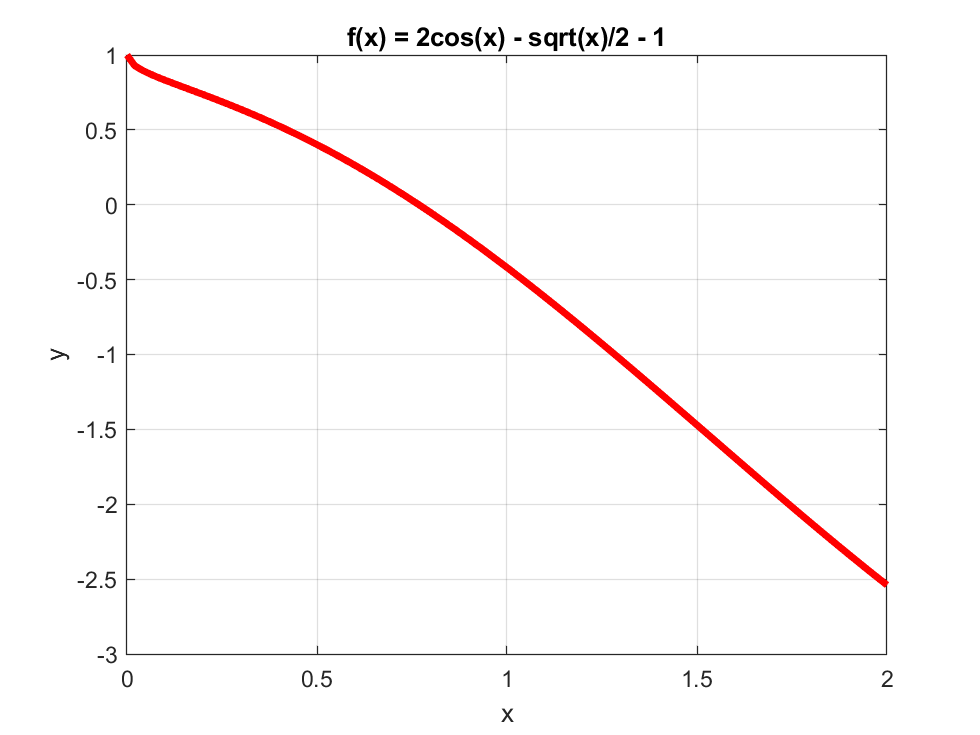

f = @(x) 2*cos(x) - sqrt(x)/2 - 1;

x = linspace(0, 2, 100);
plot(x, f(x), 'r', 'linewidth', 3)
grid on
xlabel('x')
ylabel('y')
title('f(x) = 2cos(x) - sqrt(x)/2 - 1')

Solución de la ecuación

xa = 0;
xb = 2;
errmax = 0.1;
[xr, fr, err] = secant(f, 0, 2, 0.1);

x1: 0  f1: 0  x2: 2  f2: -2.5394  x3: 0.56507  f3: 0.31325  error: 253.94
x1: 2  f1: 2  x2: 0.56507  f2: 0.31325  x3: 0.72264  f3: 0.075087  error: 21.8049
x1: 0.56507  f1: 0.56507  x2: 0.72264  f2: 0.075087  x3: 0.77232  f3: -0.0068144  error: 6.4324
x1: 0.72264  f1: 0.72264  x2: 0.77232  f2: -0.0068144  x3: 0.76818  f3: 0.00011921  error: 0.53807
x1: 0.77232  f1: 0.77232  x2: 0.76818  f2: 0.00011921  x3: 0.76825  f3: 1.806e-07  error: 0.0092499


disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = 0.76825  f(x) = 1.806e-07  Error:0.0092499%


#### Método de la secante

function [xr, fr, err] = secant(f, x1, x2, errmax)
% Función que resuelve una ecuación de una variable por 
% el método de la secante.
%
% Entradas:
%   f         Función que define la ecuación a resolver.
%   x1        Primer valor inicial.
%   x2        Segundo valor inicial.
%   errmax    Máximo error permitido para la solución.
%
% Salidas:
%   xr        Raíz de la ecuación encontrada.
%   fr        Valor de la ecuación en la raíz encontrada.
%   err       Error porcentual de la última iteración.

% Verifica que los parámetros de entrada sean válidos.
if nargin ~= 4
    error('Cantidad de parámetros de entrada no válido.')
end

if ~isscalar(x1) || ~isnumeric(x1)
    error('El valor x1 debe ser numérico y escalar.')
end

if ~isscalar(x1) || ~isnumeric(x2)
    error('El valor x1 debe ser numérico y escalar.')
end

if ~isscalar(errmax) || ~isnumeric(errmax) || errmax <= 0
    error('El valor errmax debe ser numérico, escalar y mayor a cero.')
end

% Evalúa la función en los puntos iniciales.
f1 = f(x1);
f2 = f(x2);

% Verifica si los valores iniciales son una solución.
if f1 == 0
    xr = x1;
    fr = 0;
    err = 0;
    return 
end

if f2 == 0
    xr = x2;
    fr = 0;
    err = 0;
    return 
end

% Algoritmo
err = 100*errmax;
while err > errmax
            
    % Intersección de la recta secante con el eje x
    x3 = x2 - ((x2-x1)/(f2-f1))*f2;
    f3 = f(x3);
    
    % Calcula el error actual.
    err = 100*(abs(x3 - x2)/max([abs(x3), eps]));
    
    % Despliega los valores actuales.
    disp("x1: " + x1 + "  f1: " + x1 + ...
        "  x2: " + x2 + "  f2: " + f2 + ...
        "  x3: " + x3 + "  f3: " + f3 + ...
        "  error: " + err)
    
    % Actualiza los valores de x
    x1 = x2;
    f1 = f2;
    x2 = x3;
    f2 = f3;    
end

% Guarda el resultado en las variables de salida.
xr = x2;
fr = f2;
end